# 実践ロバスト制御　第1章演習問題

clear; close all; clc;

## 問題1

**図1.2の直結フィードバック制御系において**$P=1/s$**とし、比例制御**$K=k_p>0$**を行うことを考える。このとき、**$k_p$**の値を変化させると、感度関数**$S$**、相補感度関数**$T$**、外乱抑圧特性**$PS$**のゲイン線図がどのように変わるか確認せよ。**

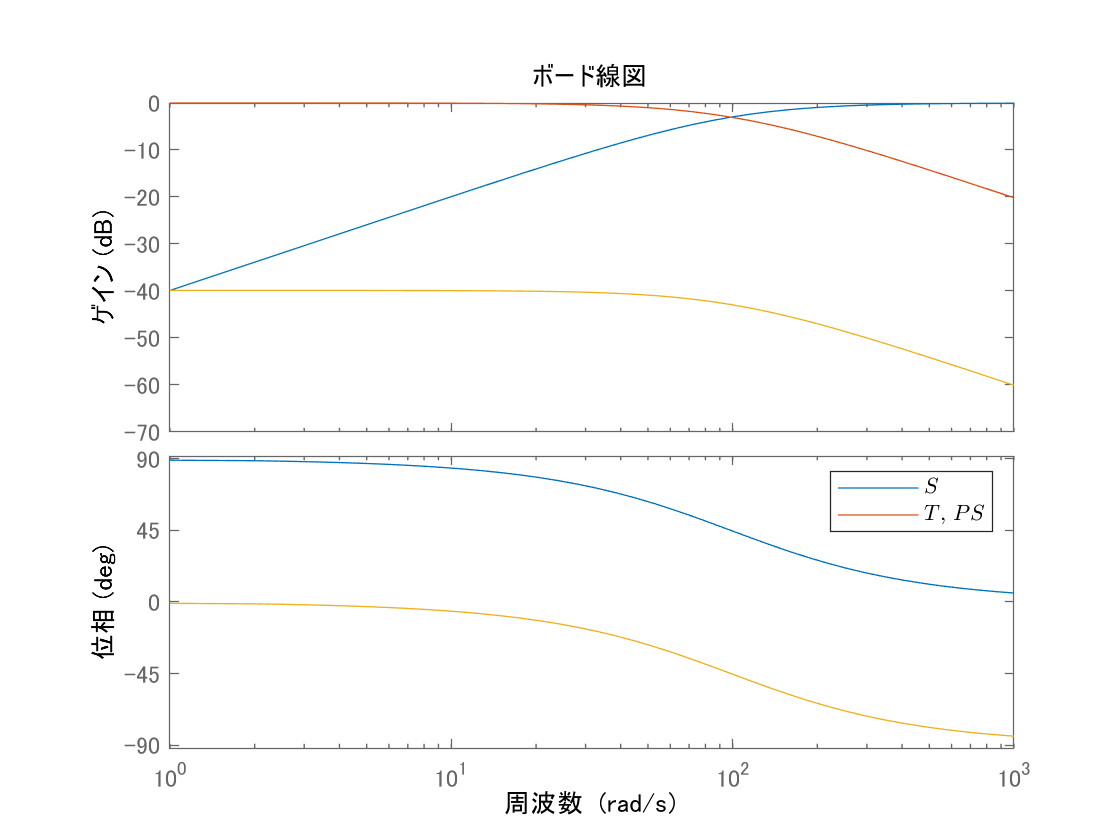

kp = 32.3;
s = tf("s");
P = 1/s;
K = kp;
S = feedback(1,P*K);
T = feedback(P*K,1);
PS = feedback(P,K);
figure;
bode(S,T,PS);
legend(["$S$", "$T$, $PS$"],"Interpreter","latex");
xlim([1 1e3]);

## 問題2

**図1.2の直結フィードバック制御系において、制御対象の伝達関数を次式とする。**


$$P=\frac{1}{10s+1}$$


**このとき、つぎの各問いに答えよ。**

s = tf("s");
P = 1/(10*s+1);

**1. 制御器を比例制御器**$K=k_p>0$**としたとき、交差周波数が**$1\:\mathrm{rad/s}$**になるように**$k_p$**を定めよ。**

wc = 1;
kp = sqrt(wc*100 + 1)

kp = 10.0499

Kp = kp;

**2. 制御器をPI制御器**$K=k_p+k_i/s$**としたとき、交差周波数が**$1\:\mathrm{rad/s}$**になるようにPIゲイン**$k_p$**、**$k_i$**を定めよ。ただし、PIゲインは**$P$**の極を**$K$**の零点で相殺するように定めることとする。**

wc = 1;
kp = wc*10

kp = 10

ki = kp/10

ki = 1

Kpi = kp + ki/s;

**3. 上記1.および2.のステップ目標値応答の違いを感度関数**$S$**のゲイン線図の違いから考察せよ。**

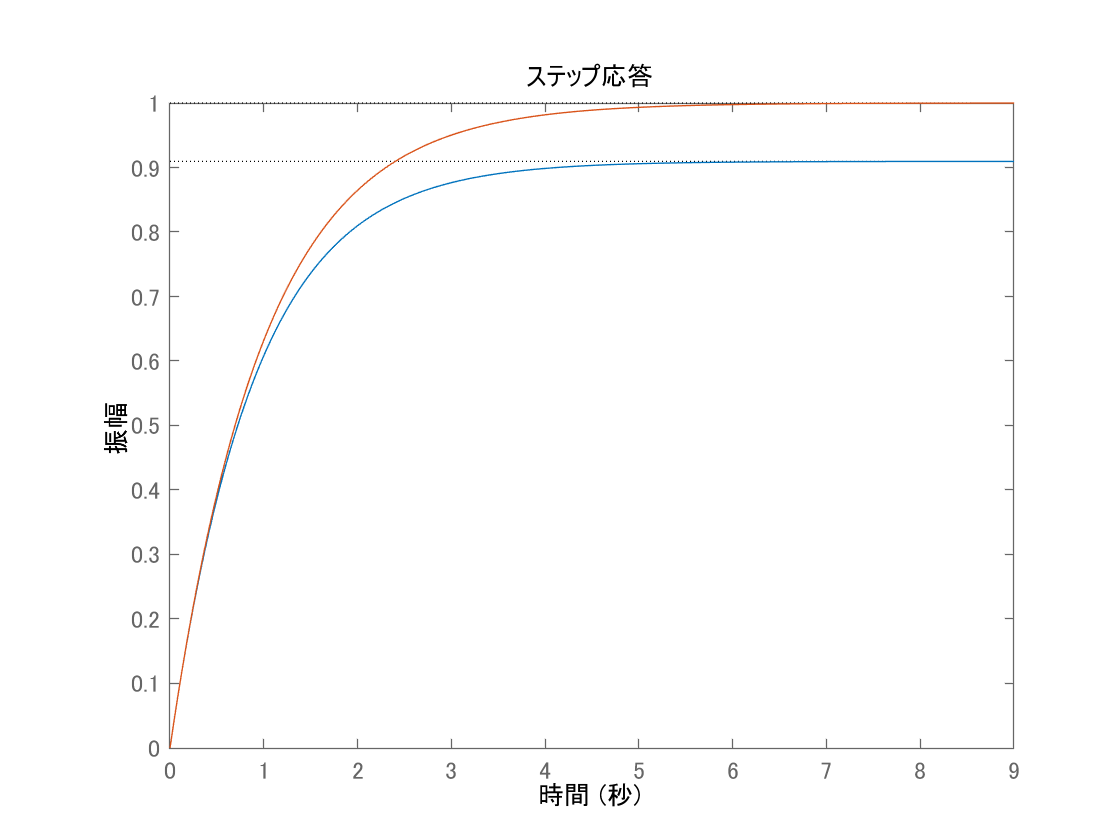

Sp = feedback(1,P*Kp);
Spi = feedback(1,P*Kpi);
Tp = feedback(P*Kp,1);
Tpi = feedback(P*Kpi,1);
figure;
step(Tp,Tpi);

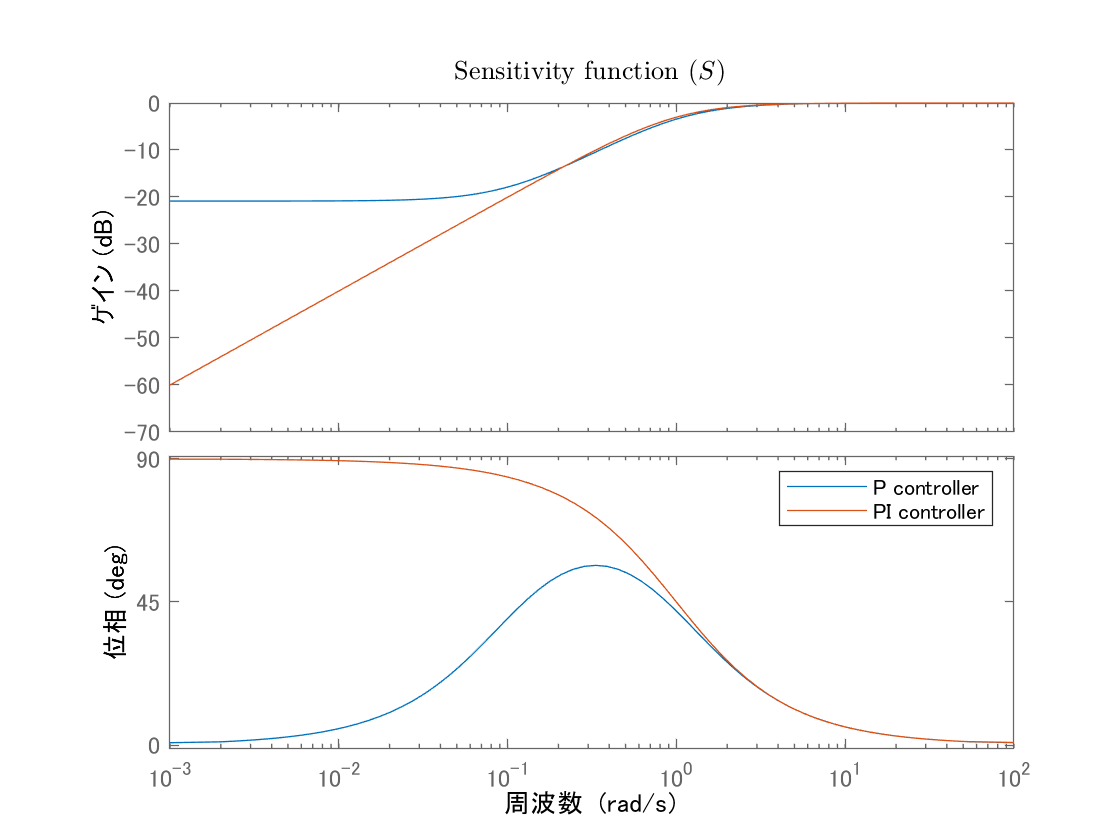

figure;
bode(Sp,Spi);
title("Sensitivity function ($S$)", "Interpreter","latex");
legend(["P controller", "PI controller"])

## 問題3

**1.3節の例では、図1.7に示したように、**$\alpha=-2.5$**の場合は応答が振動的となった。そこでノッチフィルタ**


$$N_f = \frac{s^2+2\zeta_{nf}\omega_{nf}d_{nf}s+\omega_{nf}^2}{s^2+2\zeta_{nf}\omega_{nf}s+\omega_{nf}^2}$$


**をPD制御器に乗じて、**$\omega_{nf}$**、**$\zeta_{nf}$**、**$d_{nf}$**を調整することで、応答の改善を試みよ。**

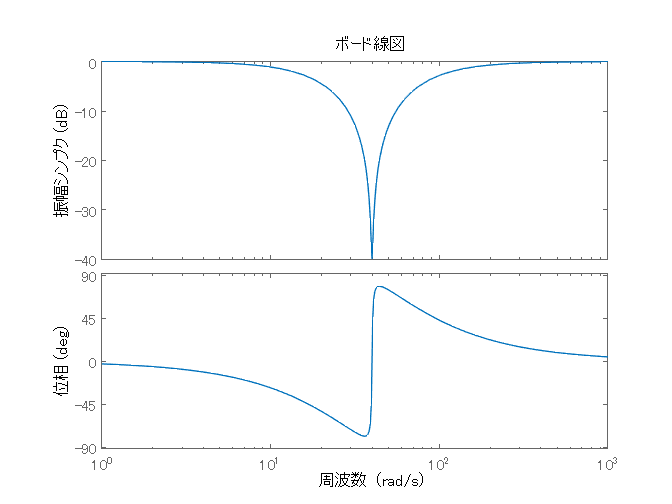

wnf = 40;
znf =1;
dnf = 0.01;
Nf = tf([1 2*znf*dnf*wnf wnf^2],[1 2*znf*wnf wnf^2]);
bode(Nf);

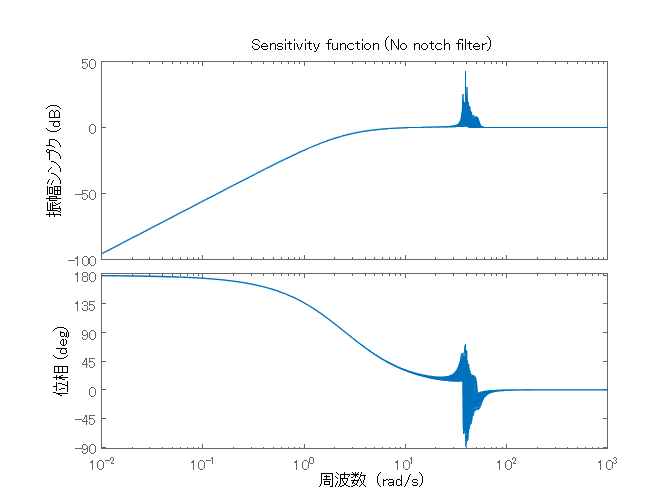

%% robust example from section 1.3
s = tf("s");
rng('default') % 乱数の初期化
M = 1;          % 質量
Pn = 1/(M*s^2); % ノミナルモデル(1/(Ms^2))
%% PD controller
alpha = -2.5;
K = alpha^2*M - 2*alpha*M*s/(0.01*s+1);
%% 摂動モデルの定義
% 以下 ureal を使って，変動パラメータを定義
m1 = ureal('m1',0.8,'percent',10); % ±10%の摂動を仮定
m2 = M - m1;                       % m1+m2=Mが成立するとする
k  = ureal('k',300,'percent',10);  % ±10%の摂動を仮定
c  = ureal('c',1,'percent',10);    % ±10%の摂動を仮定
% Two mass modelの定義
P = (c*s+k)/(s^2*(m1*m2*s^2 + (m1+m2)*c*s + (m1+m2)*k));
% モデル集合の中から50通りのモデルを選択
P = usample(P,50);
%% 摂動モデルに対する応答計算
S1 = feedback(1,P*K); % ノッチフィルタ導入前
S2 = feedback(1,P*K*Nf); % ノッチフィルタ導入後
figure;
bode(S1);
title("Sensitivity function (No notch filter)")

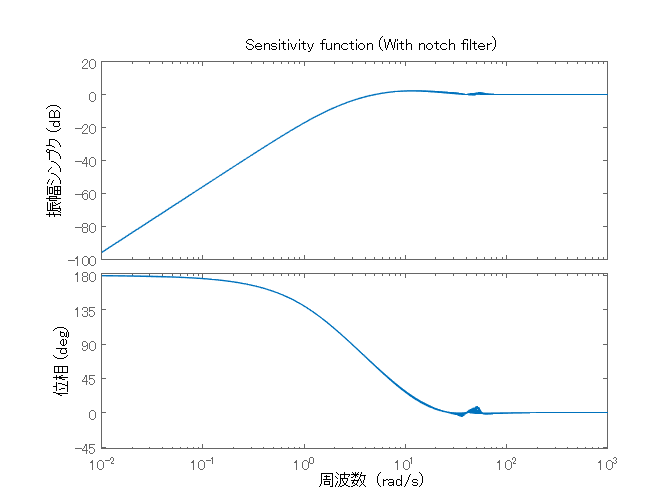

figure;
bode(S2);
title("Sensitivity function (With notch filter)")

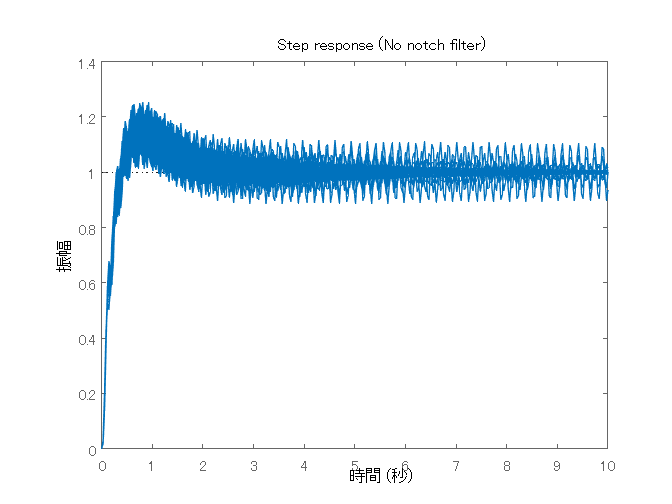

T1 = feedback(P*K,1); % ノッチフィルタ導入前
T2 = feedback(P*K*Nf,1); % ノッチフィルタ導入後
figure;
step(T1,10);
title("Step response (No notch filter)");

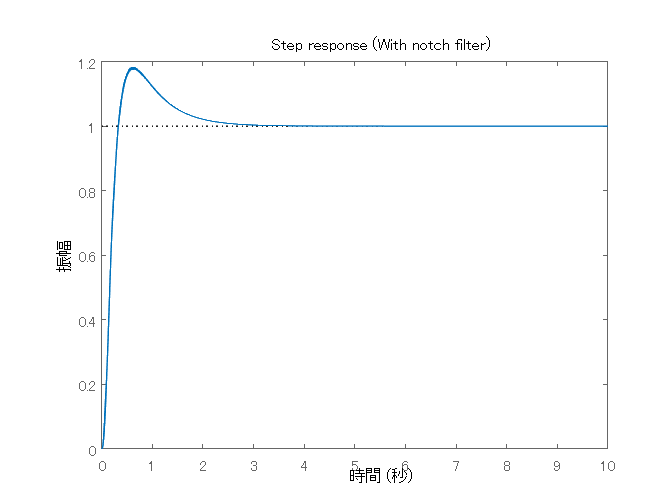

figure;
step(T2,10);
title("Step response (With notch filter)");

## 問題4

**図1.4(b)において**$p_1$**を出力**$y$**としたときの、**$u$**から**$p_1$**までの伝達関数を**$P_1$**としたとき、つぎの各問いに答えよ。**

**1. **$P_1$**を求めよ。**

P1 = (m2*s^2+c*s+k)/(s^2*(m1*m2*s^2 + (m1+m2)*c*s + (m1+m2)*k))

P1 =

  1 個の出力、1 個の入力、14 個の状態が存在する、不確かな連続時間状態空間モデル。
  モデルの不確かさは、次のブロックで構成されます:
    c: 不確かな実数、ノミナル = 1、変動性 = [-10,10]%、発生回数 2
    k: 不確かな実数、ノミナル = 300、変動性 = [-10,10]%、発生回数 2
    m1: 不確かな実数、ノミナル = 0.8、変動性 = [-10,10]%、発生回数 3

ノミナル値を確認するには "P1.NominalValue"、すべてのプロパティを確認するには "get(P1)"、不確かな要素とやりとりするには "P1.Uncertainty" と入力してください。



P1n = zpk(P1.NominalValue)

P1n =
 
   1.25 (s^2 + 5s + 1500)
  ------------------------
  s^2 (s^2 + 6.25s + 1875)
 
連続時間零点/極/ゲイン モデルです。



**2. **$P_1$**に対して、式(1.9)のPD制御器を適用して、ステップ目標値応答を求めよ。ただし、**$\alpha=-2.5$**とする。**

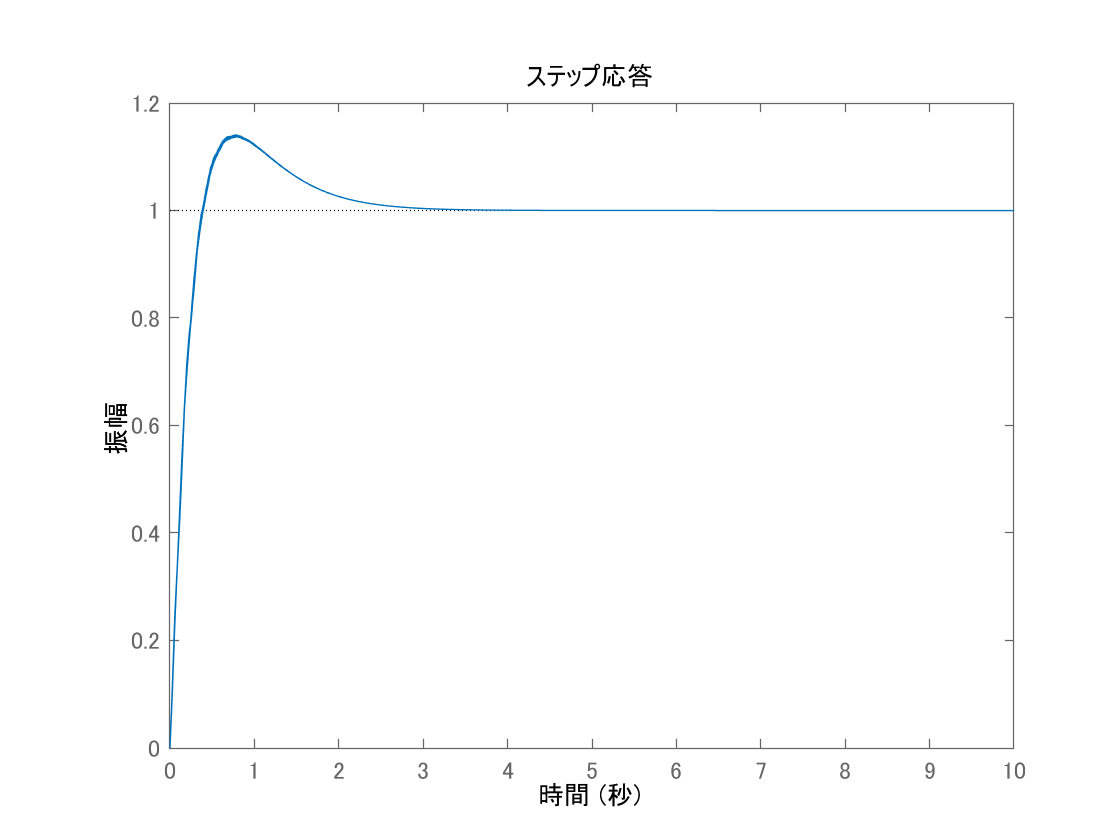

T1 = feedback(P1*K,1);
figure;
step(T1,10);

**3. 上記2.において**$\alpha=-5$**としても、閉ループ系は不安定にならないことをステップ目標値応答により確かめよ。さらに、その理由をナイキスト線図を描いて説明せよ。**

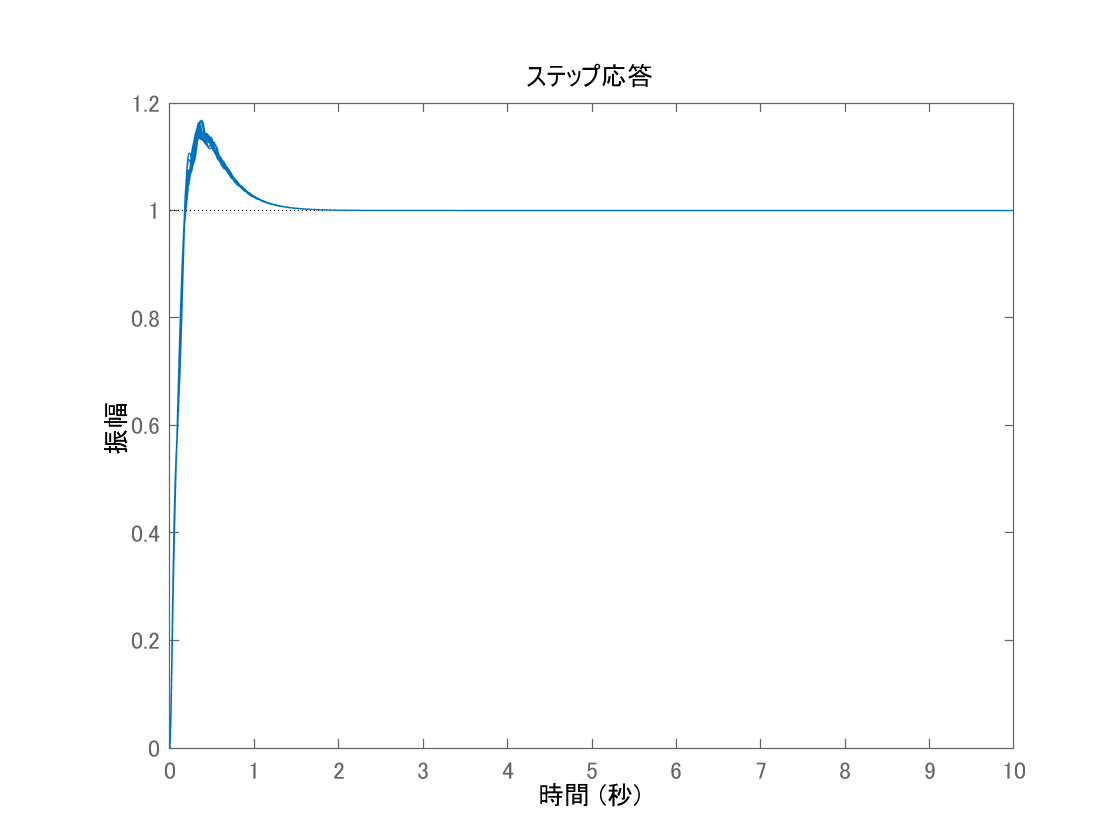

%% PD controller
alpha = -5;
K = alpha^2*M - 2*alpha*M*s/(0.01*s+1);
T1 = feedback(P1*K,1);
figure;
step(T1,10);

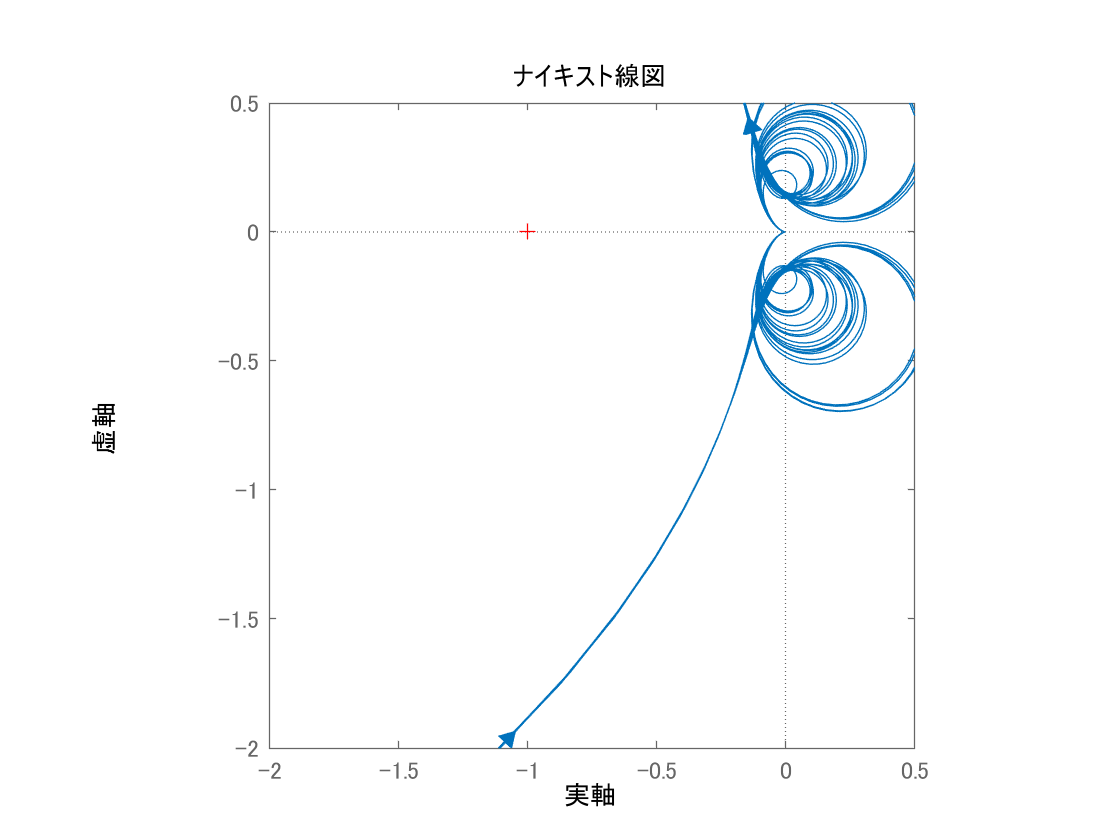

L1 = P1*K;
figure;
op = nyquistoptions("cstprefs");
op.ShowFullContour = "off";
nyquist(L1);
xlim([-2, 0.5]); ylim([-2, 0.5]);
pbaspect([1 1 1]);